## Tutorial for using SoptSC to analysis scRNA-seq data.

- SoptSC: [Cell lineage and communication network inference via optimization for single-cell transcriptomics](https://academic.oup.com/nar/article/47/11/e66/5421812), S. Wang et al., NAR, 2019.

- 10X data used in this tutorial comes from: [Single cell transcriptomics of human epidermis identifies basal stem cell transition states](https://www.nature.com/articles/s41467-020-18075-7), S. Wang, Nature Communications, 2020.

% Add tools into matlab path
clc;
addpath('Data');
addpath('package/symnmf');
addpath('package');

#### Step 1 (Required)

Load data

%% Step 1: Read 10X data
data_dir = 'Data/GRCh38'; % path where 10x data located
[count, gene_annotation, gene_ids, cell_annotation] = load_10x(data_dir,'sparse',1);

%% load the processed data
load Data/SoptSC_object.mat

%% Create SoptSC object
opt.alpha = 10;     % remove cells that express less than opt.alpha genes (default: 10)
opt.beta = 0.1;     % remove cells that express more than opt.beta*100% genes (default: 0.1)
SoptSC_object = creat_soptsc_object(count,gene_annotation,gene_ids,cell_annotation,opt);

%% save all the figures in to folder
folder = 'Results';

%% Run SoptSC to identify clusters and subpopulation composition
opt.No_cluster = [];    
opt.No_exc_cell = 10;
opt.No_features = 2000;
% opt.K = 30; % Number of neighboring cells (default: 30)
SoptSC_object = run_SoptSC(SoptSC_object,opt); % run_SoptSC

%% Change the number of cluster to be 7
No_cluster = 7;
SoptSC_object = SoptSC_change_No_cluster(SoptSC_object,No_cluster);

%% Run dimension reduction (umap)
opt.ppx = 50;   % ppx: peplexicty for umap
opt.topn = 300;
opt.input = 0; % 0: used topn gene expression as input; 1: use similarity as input
SoptSC_object = run_dimensionreduction(SoptSC_object,opt);

#### Step 2: Generating all mian figures 1 & 2 in the paper

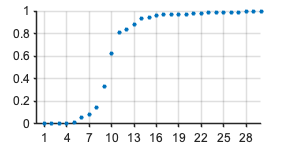

%% plot eigen-gap

plot_eigengap(SoptSC_object,folder);

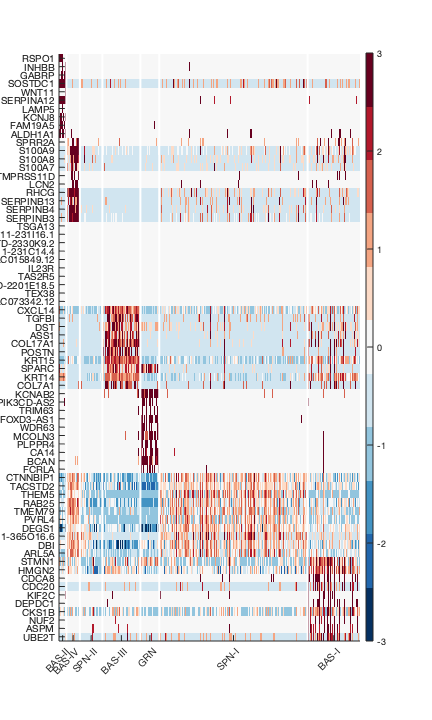

%% plot heatmap of topn DEGs
opt1.figsize = [0 0 6 10];
opt1.figname = 'GC_heatmap';
topn = 10;

plot_DEGs_heatmap(SoptSC_object,topn,folder,opt1);

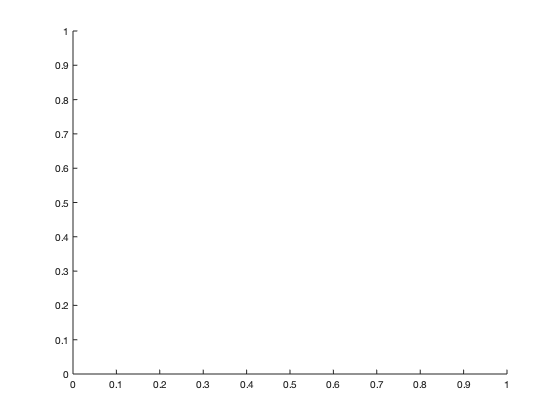

%% user-defined cluster colors: No_cluster x 3 matrix (each row represent rgb)
% zzz = hsv;
% cluster_color = zzz(1:round(256./No_cluster):end,:);

cluster_color = get(gca,'colororder');

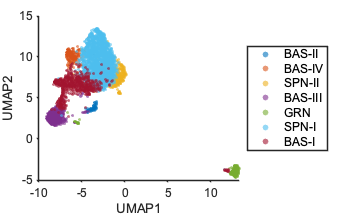

%% plot cluster
opt.figname = 'Cluster';
opt.cluster_color = cluster_color;
opt.figsize = [0 0 5 3]; % figure size

plot_cluster(SoptSC_object,folder,opt);

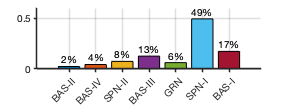

%% plot percentage of cells in each cluster
opt.figname = 'Cluster_Cell_Percantage';
opt.figsize = [0 0 4 1.5]; % figure size

plot_cell_percent(SoptSC_object,folder,opt);

%% selected markers
Marker = {'KRT14','KRT10','PTTG1','RRM2','ASS1'};

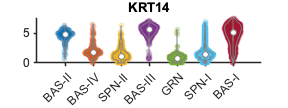

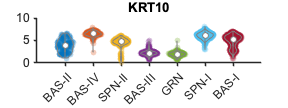

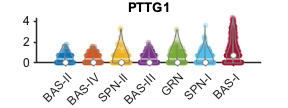

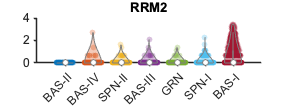

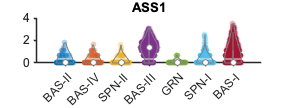

%% Violin
opt.figsize = [0 0 4 1.5];

plot_violin(SoptSC_object,Marker,folder,opt);

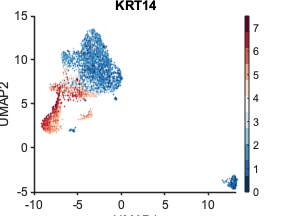

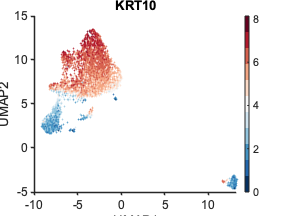

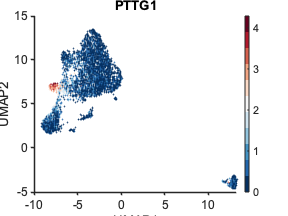

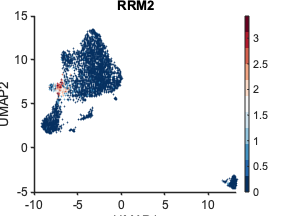

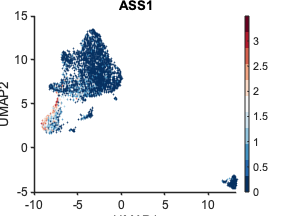

%% feature plot
opt.figsize = [0 0 4 3];

plot_marker(SoptSC_object,Marker,folder,opt);

%% user defined cluster name
SoptSC_object.cluster_name = {'BAS-II','BAS-IV','SPN-II','BAS-III','GRN','SPN-I','BAS-I'};

%% plot cluster with new cluster names
opt.figname = 'Cluster_named';
opt.cluster_color = cluster_color;
opt.figsize = [0 0 5 3]; % figure size
plot_cluster(SoptSC_object,folder,opt);

%% run lineage and pseudotime inference
opt.root_cluster = 7; 
opt.root_cell = 0;
opt.reverse = 0;
SoptSC_object = run_lineage_and_pseudotime(SoptSC_object,opt);

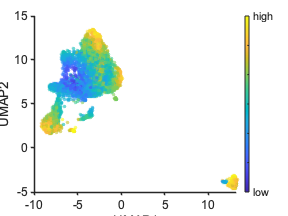

%% plot pseudotime for cells in UMAP space
opt.figname = 'Pseudotime';
opt.figsize = [0 0 4 3];

plot_pseudotime(SoptSC_object,folder,opt);

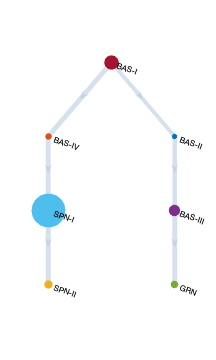

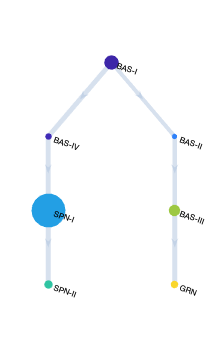

%% plot lineage tree
opt.figname = 'Lineage';
opt.figsize = [0 0 3 5];

plot_lineage(SoptSC_object,folder,opt);

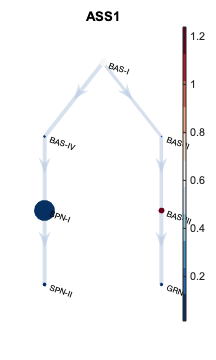

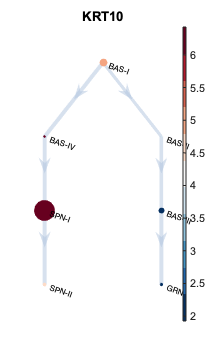

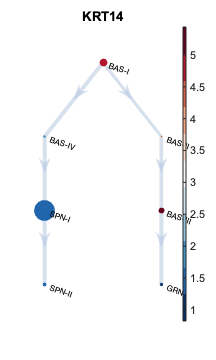

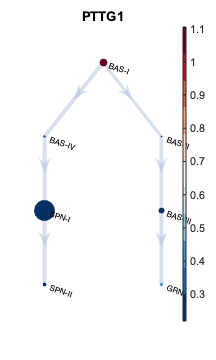

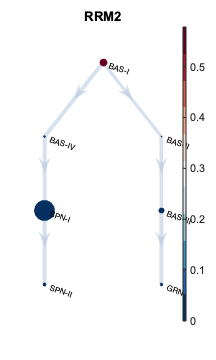

%% plot marker on lineage treee
opt.figsize = [0 0 3 5];

plot_lineage_marker(SoptSC_object,Marker,folder,opt);